# PCA - MATLAB (3 dimensiones)

Autor: Diego Vértiz Padilla Este script aplica PCA a datos con 3 variables numéricas. Calcula la matriz de covarianza y correlación, y proyecta los datos en 2D.

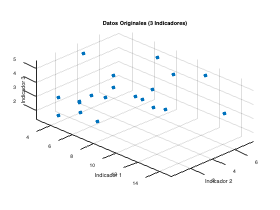

% Cargar los datos
data = readtable("indicadores_datos.csv");
X = table2array(data);

% Gráfico 3D de los datos originales (sin centrar)
figure;
scatter3(X(:,1), X(:,2), X(:,3), 60, 'filled');
xlabel("Indicador 1");
ylabel("Indicador 2");
zlabel("Indicador 3");
title("Datos Originales (3 Indicadores)");
grid on;
axis equal;
view(45, 25);  % ángulo visual opcional


% Centrar la matriz
X_centered = X - mean(X);

% Matriz de covarianza y correlación
disp("Matriz de covarianza:");

Matriz de covarianza:


disp(cov(X_centered));

   10.1168    2.2375    2.0639
    2.2375    4.2811    0.8255
    2.0639    0.8255    1.5321




disp("Matriz de correlación:");

Matriz de correlación:


disp(corrcoef(X_centered));

    1.0000    0.3400    0.5242
    0.3400    1.0000    0.3223
    0.5242    0.3223    1.0000




% Aplicar PCA
[coeff, score, latent, ~, explained] = pca(X_centered, 'Centered', false);

% Varianza explicada
disp("Varianza explicada por componente (%):");

Varianza explicada por componente (%):


disp(explained');

   71.4157   22.1420    6.4423




% Varianza acumulada
var_acum = cumsum(explained) / 100;
disp("Varianza acumulada:");

Varianza acumulada:


disp(var_acum');

    0.7142    0.9356    1.0000



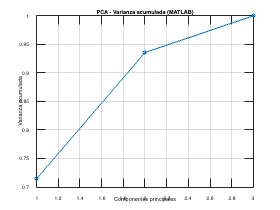


% Gráfico de varianza acumulada
figure;
plot(var_acum, '-o', 'LineWidth', 2);
xlabel("Componentes principales");
ylabel("Varianza acumulada");
title("PCA - Varianza acumulada (MATLAB)");
grid on;


% Proyección en 2D
Z = score(:, 1:2);
disp("Matriz proyectada Z (2 componentes):");

Matriz proyectada Z (2 componentes):


disp(Z(1:5, :));  % Mostrar solo las primeras filas

    4.0834   -3.4428
   -0.5177   -3.0562
   -3.2286   -0.4065
   -3.5599    2.2219
   -2.6750   -1.1934



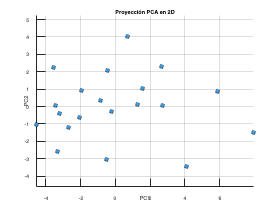


% Gráfico 2D de la proyección PCA
figure;
scatter(Z(:,1), Z(:,2), 60, 'filled', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', [0.2 0.6 0.9]);
xlabel("PC1");
ylabel("PC2");
title("Proyección PCA en 2D");
grid on;
axis equal;